# **Readme**

Dans ce live script je détaille l'exploitation de tous les scripts conçu dans le cadre de mon stage.

## Chargement des données d'IMU

Les données d'IMUs collectées avec l'application sensor logger sont enregistrées en csv, et sont chargé dans l'environnement de travail avec la fonction `readData`**, **elle prend en argument le **chemin d'accès** du dossier contenant les fichiers *.csv* et retourne **l'accéleration** en *m/s^2* `(Nx3)`, la **vitesse angulaire** en rad/s `(Nx3)`, **l'intensité du champs magnétique** en *microTesla* `(Nx3)`,** l'orientation** en **quaternion** et suivant les **angles d'euler** (yaw, roll, et pitch) en *rad/s* `(Nx3).`

[acc, gyro, magne, quat, yrp] = readData('circle_slow')

acc =          0         0         0
         0         0         0
   -0.0221   -0.1928   -0.0080
   -0.0111   -0.1588    0.0174
   -0.0963   -0.1393   -0.0492
   -0.1287   -0.0970   -0.1170
   -0.1173   -0.0367   -0.1861
   -0.1017   -0.0564   -0.1494
   -0.1508   -0.1298   -0.0381
   -0.1076   -0.1711    0.0290


gyro =    -0.1808   -0.2627   -0.0168
   -0.1830   -0.2808   -0.0232
   -0.1915   -0.2787   -0.0274
   -0.2181   -0.2563   -0.0338
   -0.2490   -0.2382   -0.0391
   -0.2671   -0.2446   -0.0338
   -0.2831   -0.2659   -0.0306
   -0.3033   -0.3000   -0.0296
   -0.3246   -0.3415   -0.0264
   -0.3395   -0.3884   -0.0168


magne =    -6.8250   -1.4438  -34.9688
   -7.2938   -1.7438  -35.2688
   -7.0875   -1.7063  -35.0250
   -7.0313   -1.8188  -34.9313
   -7.1250   -1.8750  -34.7438
   -6.9750   -1.7625  -34.8375
   -7.1438   -1.6500  -34.6875
   -7.2750   -1.6500  -34.6500
   -7.3688   -1.6688  -34.5375
   -7.3125   -1.5375  -34.4062


quat = 1901×1 quaternion array
        0.98978 +   0.074258i -   0.091856j -   0.079857k
        0.98896 +   0.073363i -   0.092573j -   0.089467k
        0.98754 +   0.059993i -    0.09325j -    0.11164k
        0.98648 +   0.053312i -   0.094088j -    0.12313k
        0.98404 +   0.047823i -   0.094283j -    0.14314k
        0.98193 +   0.043961i -   0.094474j -    0.15799k
        0.98029 +     0.0413i -   0.095195j -     0.1681k
        0.97879 +   0.038388i -   0.096198j -    0.17674k
         0.9763 +   0.034285i -   0.097036j -    0.19038k
        0.97411 +   0.030082i -   0.098139j -    0.20143k
        0.97238 +   0.025887i -   0.099673j -    0.20947k
        0.97207 +    0.02196i -    0.10158j -    0.21042k
        0.97192 +   0.018166i -    0.10322j -     0.2107k
         0.9705 +   0.013687i -    0.10385j -    0.21714k
        0.96711 +  0.0086991i -    0.10373j -     0.2321k
        0.96384 +  0.0045909i -    0.10368j -    0.24545k
        0.96174 +  0.0014003i -    0.1042

yrp =     0.1469   -0.1731   -0.1624
    0.1663   -0.1731   -0.1624
    0.2130   -0.1733   -0.1398
    0.2371   -0.1748   -0.1287
    0.2783   -0.1740   -0.1214
    0.3089   -0.1737   -0.1164
    0.3297   -0.1748   -0.1132
    0.3476   -0.1767   -0.1094
    0.3759   -0.1783   -0.1041
    0.3989   -0.1809   -0.0983


## Implementation du filtre de Kalman et estimation de l'orientation

L'implémentation du filtre de kalman se fait en utilisant la fonction `ahrsfilter` de la `Sensor Fusion and Tracking Toolbox`, disponible depuis la version `2018b` de Matlab. Si elle n'est pas disponible parmis packages suivez le lien suivant :  [https://fr.mathworks.com/videos/add-on-explorer-106745.html](https://fr.mathworks.com/videos/add-on-explorer-106745.html)

% Fréquence d'acquisition des données d'IMU en Hz
Fs = 100; 
% Definition du filtre
fuse = ahrsfilter('SampleRate',Fs)

fuse =   ahrsfilter with properties:

                        SampleRate: 100               Hz      
                  DecimationFactor: 1                         
                AccelerometerNoise: 0.00019247        (m/s²)² 
                    GyroscopeNoise: 9.1385e-05        (rad/s)²
                 MagnetometerNoise: 0.1               (µT)²   
               GyroscopeDriftNoise: 3.0462e-13        (rad/s)²
           LinearAccelerationNoise: 0.0096236         (m/s²)² 
          MagneticDisturbanceNoise: 0.5               (µT)²   
     LinearAccelerationDecayFactor: 0.5                       
    MagneticDisturbanceDecayFactor: 0.5                       
     ExpectedMagneticFieldStrength: 50                µT      
               InitialProcessNoise: [12⨯12 double]            
                 OrientationFormat: 'quaternion'              


% Estimation de l'orientation en quaternion 
quat_est = fuse(acc,gyro,magne)

quat_est = 1901×1 quaternion array
        0.99998 -  0.0009035i -  0.0055713j + 0.00010099k
        0.99994 -  0.0016678i -   0.010791j + 0.00015808k
        0.99989 -  0.0026666i -   0.014629j + 0.00011536k
        0.99984 -  0.0036461i -   0.017373j - 1.8871e-05k
         0.9998 -  0.0047348i -   0.019318j - 0.00022243k
        0.99976 -  0.0058766i -   0.021024j - 0.00041923k
        0.99971 -  0.0070516i -   0.022861j - 0.00060548k
        0.99966 -  0.0083667i -   0.024868j - 0.00078942k
        0.99959 -  0.0098585i -   0.027002j - 0.00095758k
         0.9995 -   0.011453i -   0.029393j -  0.0010797k
         0.9994 -   0.013093i -   0.032049j -  0.0011584k
        0.99928 -   0.014796i -   0.034792j -  0.0012568k
        0.99916 -   0.016529i -   0.037351j -  0.0014214k
        0.99905 -   0.018402i -   0.039503j -  0.0016108k
        0.99895 -   0.020281i -    0.04111j -  0.0017511k
        0.99885 -   0.022024i -   0.042579j -  0.0017866k
        0.99874 -   0.023631i -   0.0

% OU l'on peut aussi estimer la vitesse angulaire par le filtre
%[quat_est, gyro_est] = fuse(acc,gyro,magne)

### Calcul de l'erreur d'estimation rms1

L'erreur d'estimation de l'orientation est évaluée comme la ***"root mean square error"***  de la distance en quaternion entre la valeur estimée et la vérité terrain, elle implementé dans la fonction `loss2qad.`

rms1 = loss2qad(quat, quat_est)

rms1 = 79.5513

## Optimisation du filtre 

Le filtre crée precedent possède des paramètres qui influent sur la qualité de l'estimation, alors il est necessaire d'avoir les bonnes valeurs ou faire une bonne optimisation de ces derniers, à cet effet Matlab prose une fonction pour le faire `tune`**, **qui se sert de l'orientation en vérité de terrain pour optimiser les paramètres du filtres.

La fonction `tuneKF` prend en paramètre les données d'accéleration, de vitesse angulaire, d'intensité du champs magnetique, la vérite terrain de l'orientation en quaternion et le filtre a optimisé et retourne les paramètres optimisé du filtre dans une structure matlab.

filterParams = tuneKF(acc,gyro,magne,quat,fuse)

filterParams = struct with fields:
    Value: [4.4946e-04 1.5766e-06 13.4355 2.0968e-16 1.2930 26.7894 1.0000 1.0000]
     Name: 'AccelerometerNoiseGyroscopeNoiseMagnetometerNoiseGyroscopeDriftNoiseLinearAccelerationNoiseMagneticDisturbanceNoiseLinearAccelerationDecayFactorMagneticDisturbanceDecayFactor'


% Estimation de l'orientation avec le filtre optimisé 
quat_estOpt = fuse(acc,gyro,magne);

### Calcul de la nouvelle erreur d'estimation rms2

rms2 = loss2qad(quat, quat_estOpt)

rms2 = 24.6485

#### Comparaison de rms1 et rms2

`rms1 = 79.553  < rms2 = 24.6485, `le filtre optimisé est plus performant.

## Estimation de la trajectoire tridimensionnelle 

L'estimation de la trajectoire tridimensionnelle se fait avec la fonction `handPosition, `qui prend en paramètre **l'orientation** suivant les angles d'euler yaw (axe z), roll (axe y), pitch (axe x) en rad/s, la **longueur du bras**, et la **distance du centre de pression (COP) à l'épaule **et renvoie la position en x, y et z.

% Conversion de l'orientation suivant les angles d'euler
yrp_est = euler(quat_estOpt,'ZYX', 'frame')

yrp_est =    -0.0002   -0.0029   -0.0018
   -0.0004   -0.0059   -0.0036
   -0.0006   -0.0088   -0.0055
   -0.0009   -0.0114   -0.0077
   -0.0013   -0.0138   -0.0102
   -0.0016   -0.0163   -0.0129
   -0.0019   -0.0190   -0.0157
   -0.0021   -0.0220   -0.0187
   -0.0023   -0.0255   -0.0219
   -0.0024   -0.0294   -0.0253


% Définition des longueurs de bras et distance COP-épaule
armLength = 0.224;
cop2shoulder = 0.0448;
% Calcul de la trajectoire
pos3D = handPosition(yrp_est, armLength, cop2shoulder);
size(pos3D)

ans =            3        1902


## Estimation de la surface et le volume de travail et tracé de la trajectoire 3D

L'estimation de la surface et du volume de travail se fait avec la fonction plotPos3D et trace aussi la trajectoire 3D en niveau de couleur (peut être mis en `%commentaire` si non necessaire)

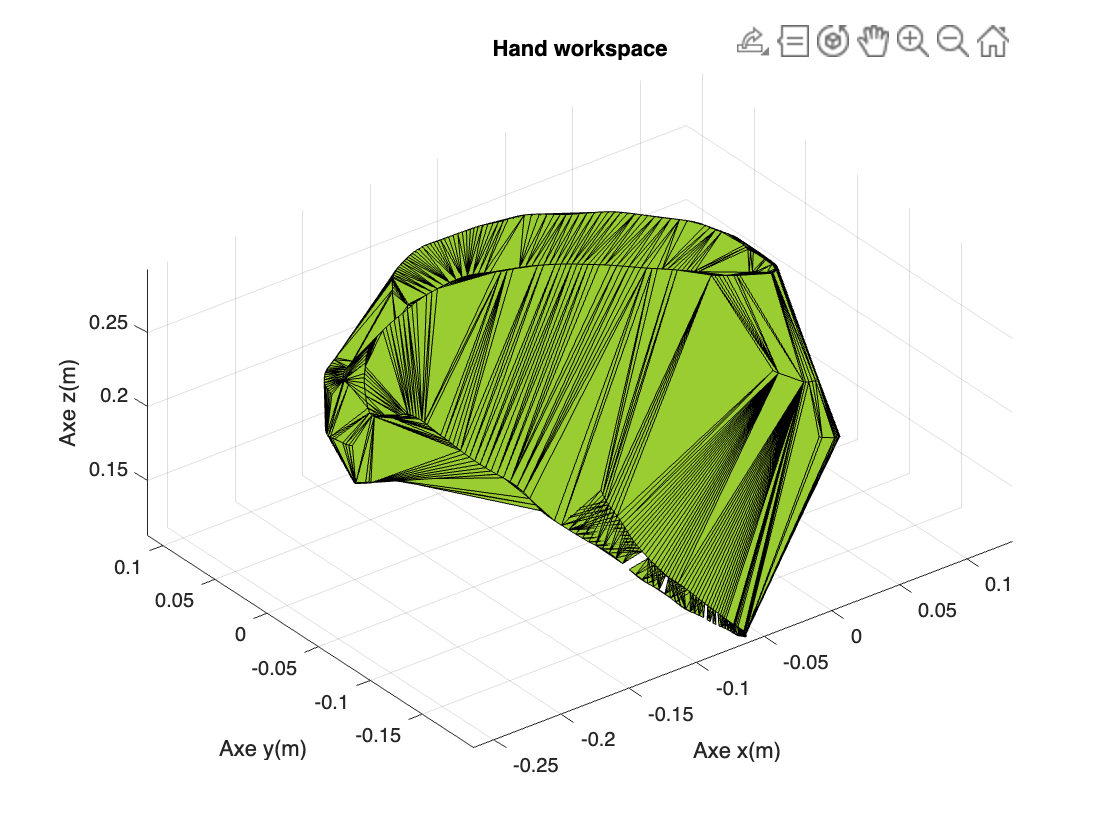

surf = 0.1815

vol = 0.0043

[surf, vol] = plotPos3D(pos3D)

## Evaluation des descripteurs de finesse : Travel path, jerk, surface et volume de travail

La fonction `assesment `prend en paramètre la position 3D (3xN), les accélérations (Nx3) , les vitesses angulaires (Nx3) et la longueur du bras et renvoie la **surface**, **le volume de travail**, **la vitesse**, la **norme de l'accéleration**, le **jerk** et le **travel path.**

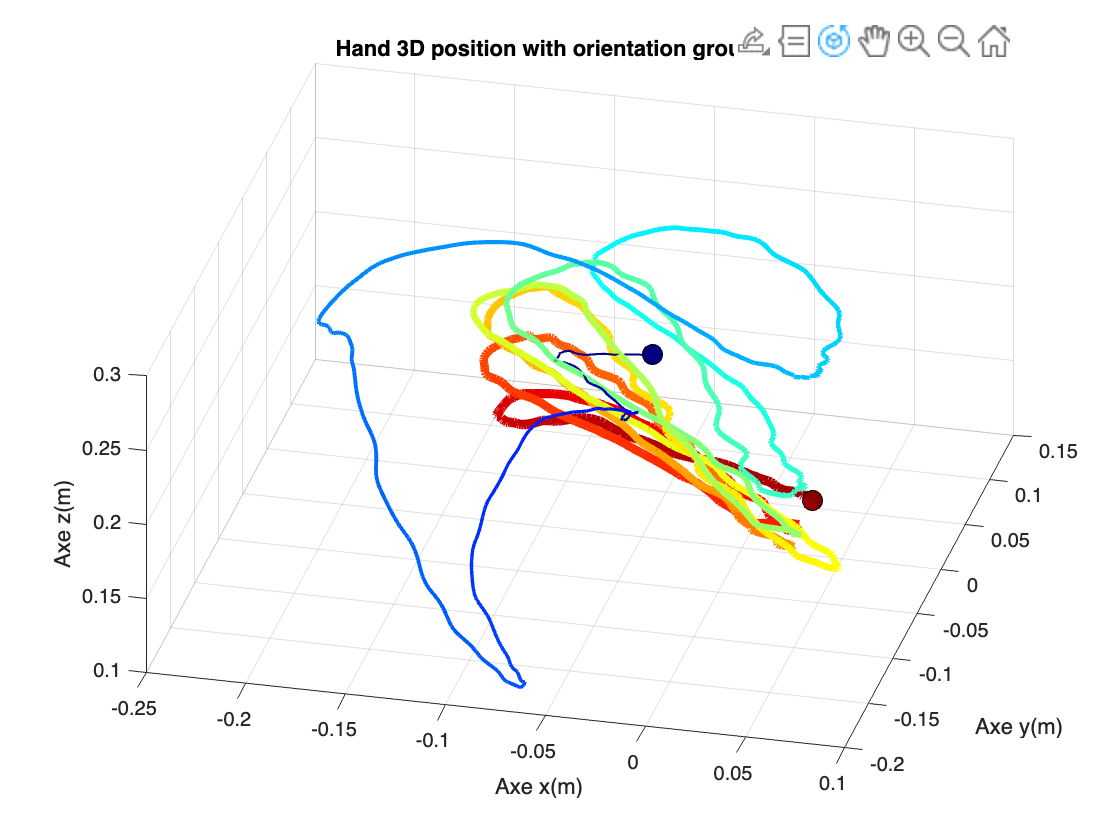

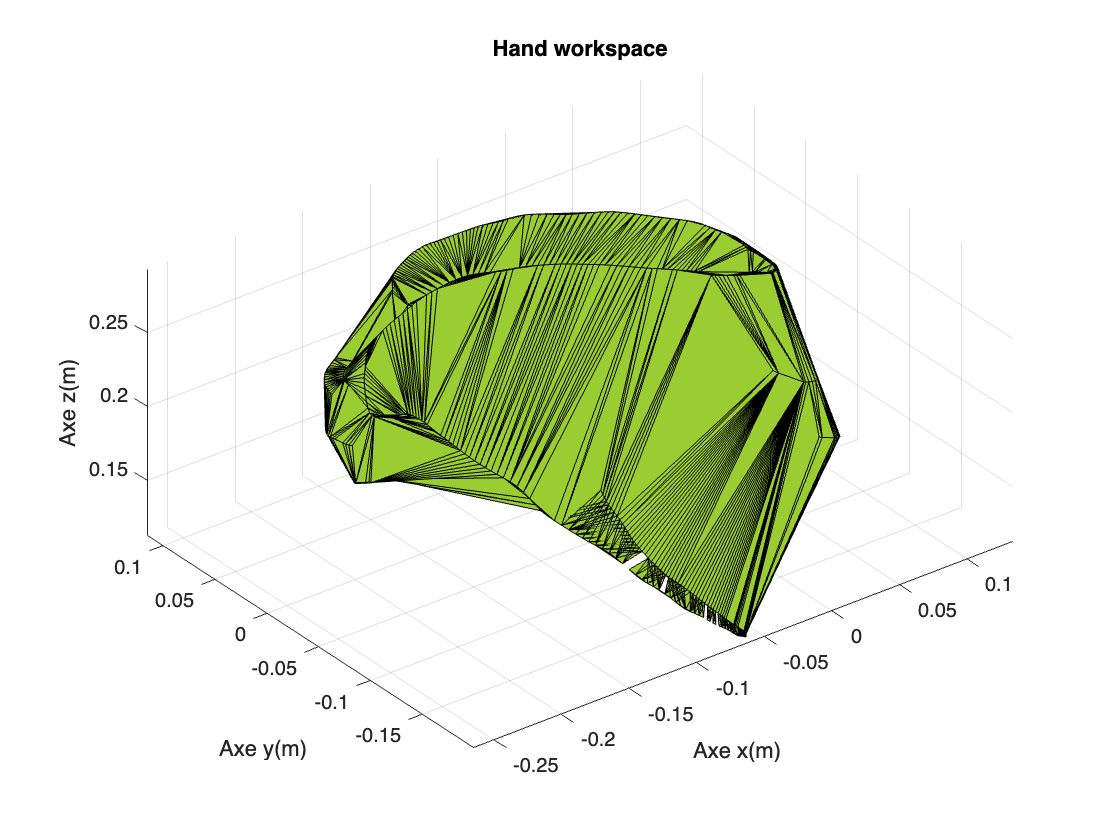

surface = 0.1815

volume = 0.0043

velocity =     0.0715    0.0753    0.0760    0.0758    0.0777    0.0815    0.0873    0.0958    0.1057    0.1156    0.1226    0.1226    0.1192    0.1136    0.1053    0.1012    0.1025    0.1071    0.1157    0.1261    0.1331    0.1320    0.1244    0.1200    0.1219    0.1235    0.1222    0.1112    0.0875    0.0713    0.0590    0.0462    0.0353    0.0300    0.0296    0.0214    0.0142    0.0158    0.0157    0.0158    0.0185    0.0176    0.0200    0.0312    0.0418    0.0482    0.0579    0.0674    0.0701    0.0612


acceleration =          0         0    0.1943    0.1601    0.1763    0.1992    0.2230    0.1893    0.2026    0.2042    0.2447    0.3448    0.4005    0.5455    0.5020    0.3491    0.2292    0.1491    0.1690    0.2665    0.3210    0.1683    0.0777    0.1843    0.5275    1.1022    1.9249    2.2360    2.1496    2.0342    1.6243    1.3141    1.0900    0.7809    0.8110    0.7403    0.6678    0.7151    0.8208    0.8081    0.7396    0.6403    0.6391    0.5034    0.3760    0.3445    0.3064    0.2493    0.1736    0.1684


Jerk =          0    0.1943   -0.0341    0.0162    0.0228    0.0238   -0.0336    0.0132    0.0016    0.0405    0.1001    0.0557    0.1450   -0.0435   -0.1529   -0.1199   -0.0801    0.0198    0.0976    0.0545   -0.1527   -0.0906    0.1066    0.3432    0.5747    0.8227    0.3110   -0.0863   -0.1154   -0.4099   -0.3102   -0.2241   -0.3091    0.0301   -0.0707   -0.0725    0.0473    0.1057   -0.0127   -0.0685   -0.0993   -0.0012   -0.1357   -0.1274   -0.0315   -0.0381   -0.0571   -0.0757   -0.0053   -0.0494


TP = 4.4739

[surface,volume,velocity,acceleration,Jerk,TP] = assesment(pos3D,acc,gyro,armLength)

## Evaluation de la géneralisation du filtre de kalman

Diverses trajectoires ont été generées (08) afin d'évaluer la géneralisation du filtre de kalman.

***Protocole mis en oeuvre: ***une trajectoire de référence est sélectionnée, puis un filtre est ajusté pour optimiser son comportement sur cette trajectoire. Ensuite, ce filtre optimisé est évalué en utilisant les autres trajectoires. Pour ces trajectoires supplémentaires, nous itérons le processus d’optimisation en ajus-tant un nouveau filtre, et nous évaluons les descripteurs de ces trajectoires en les comparant à la trajectoire de référence précédemment établie.

Le script validation implémente ce protocole et stocke le résultats dans la structure `Validation`, *i.e. *les erreurs loss1 entre les descripteurs évaluée sur la trajectoire de réference et ceux évalués sur les autres trajectoires.

% Exécution du script
% validation
% Validation est la structure qui stocke erreurs dans des tableaux 
% circle_slow2circle_fast est l'erreur des descripteurs avec comme
% trajectoire de réference circle_slow et la trajectoire courante
% circle_fast